# When using coincident measurements between VOCALS-REx and MODIS, how do I select which MODIS pixels to use?

Andrew John Buggee

## Load MODIS and VOCALS data set

addLibRadTran_paths;
scriptPlotting_wht;

% Load modis data and create input structure
clear variables

% Determine which computer you're using
computer_name = whatComputer;

% Find the folder where the mie calculations are stored
% find the folder where the water cloud files are stored.
if strcmp(computer_name,'anbu8374')==true

    % -----------------------------------------
    % ------ Folders on my Mac Desktop --------
    % -----------------------------------------

    % Define the MODIS folder name

    % ----- November 9th at decimal time 0.611 (14:40) -----
    %modisFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/MODIS_Cloud_Retrieval/MODIS_data/2008_11_09/';


    % ----- November 11th at decimal time 0.604 (14:30) -----
    %modisFolder = ['/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/MODIS_Cloud_Retrieval/MODIS_data/2008_11_11_1430/'];


    % ----- November 11th at decimal time 0.784 (18:50) -----
    modisFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/MODIS_Cloud_Retrieval/MODIS_data/2008_11_11_1850/';

    % ----------------------------------------
    % ***** Define the VOCALS-REx Folder *****
    % ----------------------------------------

    % ----- November 9th data -----
%     vocalsRexFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/VOCALS_REx/2008_11_09/';
%     vocalsRexFile = 'RF11.20081109.125700_213600.PNI.nc';



    % ----- November 11 data -----
    vocalsRexFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/VOCALS_REx/2008_11_11/';
    vocalsRexFile = 'RF12.20081111.125000_214500.PNI.nc';



elseif strcmp(computer_name,'andrewbuggee')==true



    % -------------------------------------
    % ------ Folders on my Macbook --------
    % -------------------------------------


    % Define the MODIS folder name

    % ----- November 9th at decimal time 0.611 (14:40) -----
    modisFolder = '/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/MODIS_Cloud_Retrieval/MODIS_data/2008_11_09/';


    % ----- November 11th at decimal time 0.604 (14:30) -----
    %modisFolder = ['/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/MODIS_Cloud_Retrieval/MODIS_data/2008_11_11_1430/'];


    % ----- November 11th at decimal time 0.784 (18:50) -----
    %modisFolder = '/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/MODIS_Cloud_Retrieval/MODIS_data/2008_11_11_1850/';




    % ----------------------------------------
    % ***** Define the VOCALS-REx Folder *****
    % ----------------------------------------



    % ----- November 9 data -----
    vocalsRexFolder = '/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/VOCALS_REx/2008_11_09/';
    vocalsRexFile = 'RF11.20081109.125700_213600.PNI.nc';


end



% Read in MODIS data
[modis,L1B_fileName] = retrieveMODIS_data(modisFolder);

% Read in VOCALS-REx data
vocalsRex = readVocalsRex([vocalsRexFolder,vocalsRexFile]);


% ----- Create a structure defining inputs of the problem -----

%modisInputs = create_modis_inputs(modisFolder, L1B_fileName);



## Plot the entire VOCALS-REx flight path on top of MODIS reflectance data

% Plot MODIS measured relfectance at some channel with VOCALS flight path

channel2plot = 1:7;
bandNames = modisBands(channel2plot);

for ii = 1:length(channel2plot)

    figure; geoscatter(modis.geo.lat(:), modis.geo.long(:), 10, ...
        reshape(modis.EV1km.reflectance(:,:,channel2plot(ii)),[],1),'.');
    cb = colorbar;
    set(get(cb, 'label'), 'string', 'Reflectance $(1/sr)$','Interpreter','latex', 'Fontsize',22)
    set(gca, 'FontSize',25)
    set(gca, 'FontWeight', 'bold')
    set(gcf, 'Position', [0 0 600 550])


    title(['Reflectance ', num2str(round(bandNames(ii,1))), '$\; nm$'],'Interpreter','latex', 'FontSize', 40)
    hold on
    geoscatter(vocalsRex.latitude, vocalsRex.longitude, 10, "red",'*')

end


## What does the raw VOCALS-REx data look like?

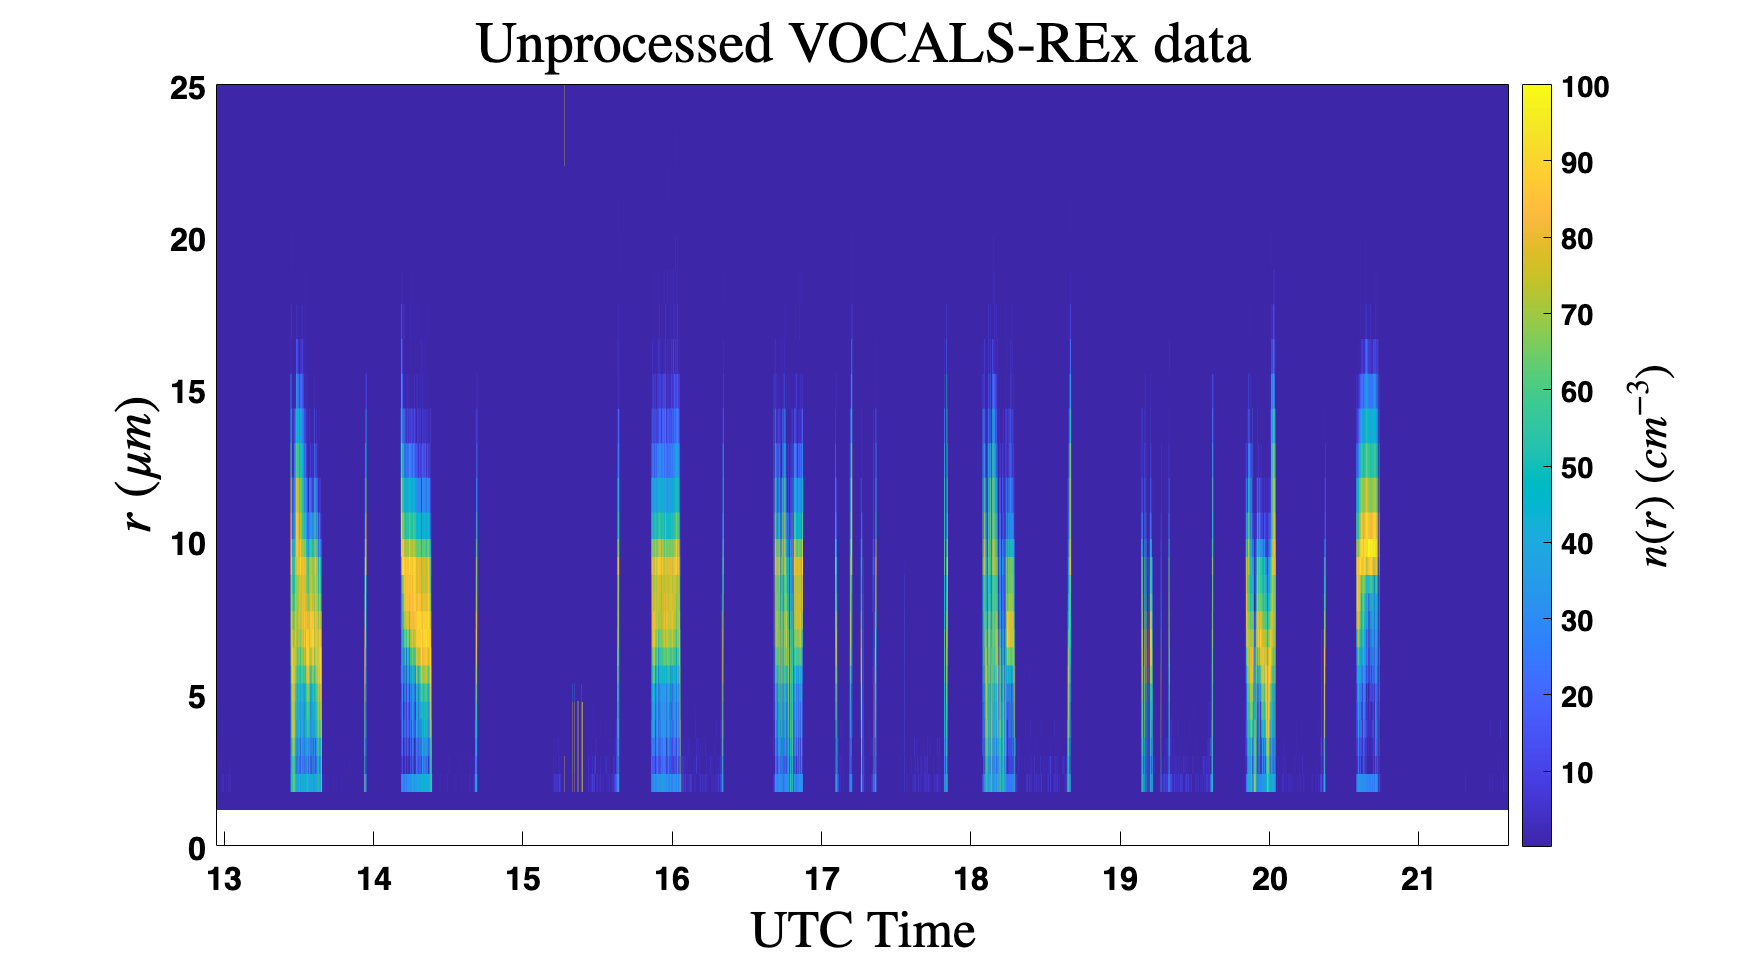

% Let's plot the raw VOCALS-REx data as a function of r on the y axis, time
% on the x axis and N as the color

figure;

% plot the droplet sizes on the x-axis
Y_data = vocalsRex.drop_radius_bin_center;

% plot the optical depth on the y-axis
X_data = vocalsRex.time_utc;


[X,Y] = meshgrid(X_data, Y_data);

s = pcolor(X,Y,vocalsRex.Nc);

% reduce the transparancy of the bin edges
s.EdgeAlpha = 0;

ylabel('$r$ $(\mu m)$', 'Interpreter','latex')
xlabel('UTC Time', 'Interpreter','latex')
title('Unprocessed VOCALS-REx data', 'Interpreter','latex')

c = colorbar;
set(gca,'ColorScale','log')
% define a colorbar label
ylabel(c,'$n(r)$ $(cm^{-3}$)','FontSize',25, 'interpreter', 'latex');

% set the total number of droplets limit
set(gca,'CLim', [10^(-1) , 10^2])

% define radius limits to plot
ylim([0 25])

% define the size of the plot
set(gcf, 'Position', [0 0 1000 550])


clear X Y X_data Y_data s c

## Plot Entire VOCALS-REx data set with MODIS recorded time

% Plot VOCALS-REx total number concentration versus altitude and droplet
% size versus altitude

%  Below this, create a subplot with effective radius versus time and
%  altitude versus time


figure; subplot(2,1,1)
semilogy(vocalsRex.time_utc, vocalsRex.total_Nc); 
grid on; grid minor; 
ylabel('Total $N_c$  $(cm^{3})$','Interpreter','latex')
title('VOCALS-REx flight Data', 'Interpreter','latex')

hold on;
yyaxis right; 
plot(vocalsRex.time_utc, vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% insert a vertical line representing the time when MODIS recorded data
xline(modis.time_decimal, 'LineWidth', 3, 'Label','MODIS', 'FontSize', 17)

% grab current axes
ax1 = gca;

subplot(2,1,2)
plot(vocalsRex.time_utc, vocalsRex.re); 
grid on; grid minor; 
xlabel('UTC Time','Interpreter','latex')
ylabel('$r_e$ $(\mu m)$','Interpreter','latex')

hold on;
yyaxis right; 
plot(vocalsRex.time_utc, vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% insert a vertical line representing the time when MODIS recorded data
% define the MODIS UTC time in decimal notation

xline(modis.time_decimal, 'LineWidth', 3, 'Label','MODIS', 'FontSize', 17)

% grab current axes
ax2 = gca;

linkaxes([ax1 ax2],'x');


set(gcf, 'Position',[0 0 1275, 600])


## Plot the vertical profile closest to the MODIS recorded time

% define the time window to plot
% this is expressed in minutes +/- the MODIS recorded time
time2plot = 1.75;      % minutes

figure; subplot(2,1,1)
semilogy(double(vocalsRex.time_utc), vocalsRex.total_Nc); 
grid on; grid minor; 
ylabel('Total $N_c$  $(cm^{3})$','Interpreter','latex')
title('VOCALS-REx flight Data', 'Interpreter','latex')

% ----- SET BOUNDARIES -----
ylim([1e-2, 1e3])
xlim([modis.time_decimal - (time2plot/60), modis.time_decimal + (time2plot/60)])

hold on;
yyaxis right; 
plot(double(vocalsRex.time_utc), vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% insert a vertical line representing the time when MODIS recorded data
xline(modis.time_decimal, 'LineWidth', 3, 'Label','MODIS', 'FontSize', 17)

% grab current axes
ax1 = gca;

subplot(2,1,2)
plot(double(vocalsRex.time_utc), vocalsRex.re); 
grid on; grid minor; 
xlabel('UTC Time','Interpreter','latex')
ylabel('$r_e$ $(\mu m)$','Interpreter','latex')

% ----- SET BOUNDARIES -----
xlim([modis.time_decimal - (time2plot/60), modis.time_decimal + (time2plot/60)])

hold on;
yyaxis right; 
plot(double(vocalsRex.time_utc), vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% insert a vertical line representing the time when MODIS recorded data
xline(modis.time_decimal, 'LineWidth', 3, 'Label','MODIS', 'FontSize', 17)

% grab current axes
ax2 = gca;

linkaxes([ax1 ax2],'x');


set(gcf, 'Position',[0 0 1275, 600])

## Find all Vertical Profiles

% First I find all vertical profiles in the VOCALS-REx flight data

lwc_threshold = 0.03;           % g/m^3
stop_at_max_lwc = false;         % truncate profile after the maximum lwc value

% ----- Find all vertical profiles within VOCALS-REx data ------
vert_prof = find_verticalProfiles_VOCALS_REx(vocalsRex, lwc_threshold, stop_at_max_lwc);


## Plot a single histogram of the raw data at any moment in time


plot_dropDistribution_topAndBottom_hist(vert_prof, 1, [0, 32])

## What do these vertical profiles look like?

% plot all profiles on a single plot


% Do you want to normalize the vertical axis of all profiles so the optical
% depth ranges between 0 and 1?
normalize_opticalDepth = false;


plot_LWC_and_re_vs_opticalDepth(vert_prof, 1:length(vert_prof.re), normalize_opticalDepth)

% plot profiles of droplet size and LWC versus optical depth
for nn = 1:5
    plot_LWC_and_re_vs_opticalDepth(vert_prof, nn, normalize_opticalDepth)
    title(['UTC Time: ',num2str(median(vert_prof.time_utc{nn}))], 'Interpreter','latex')
end

% plot all vertical profiles found 
plot_vocalsRex_vertical_profiles_pcolor_vs_optical_depth(vocalsRex, vert_prof, 1:4, false)

## Find the vertical profile closest in time to the MODIS overpass

## Then find the MODIS pixels closest in space to VOCALS-REx

% ----- Find all vertical profiles within VOCALS-REx data ------
% find all vertical profiles in the vocals-REx data set. Vertical profiles
% qualify if the total number concentration is above 10^0 and relatively
% flat, the plane is climbing in altitude, and clears the cloud deck from
% bottom to top. If this is all true, save the vocals rex data
lwc_threshold = 0.03;           % g/m^3
stop_at_max_lwc = false;         % truncate profile after the maximum lwc value

% Lets only keep the vocalsRex data we need
% Time is measured in seconds since the startTime

vocalsRex_closest2modis = cropVocalsRex2MODIS(vocalsRex, lwc_threshold, stop_at_max_lwc, modis);


## Distance between VOCALS-REx and the neighboring Pixels

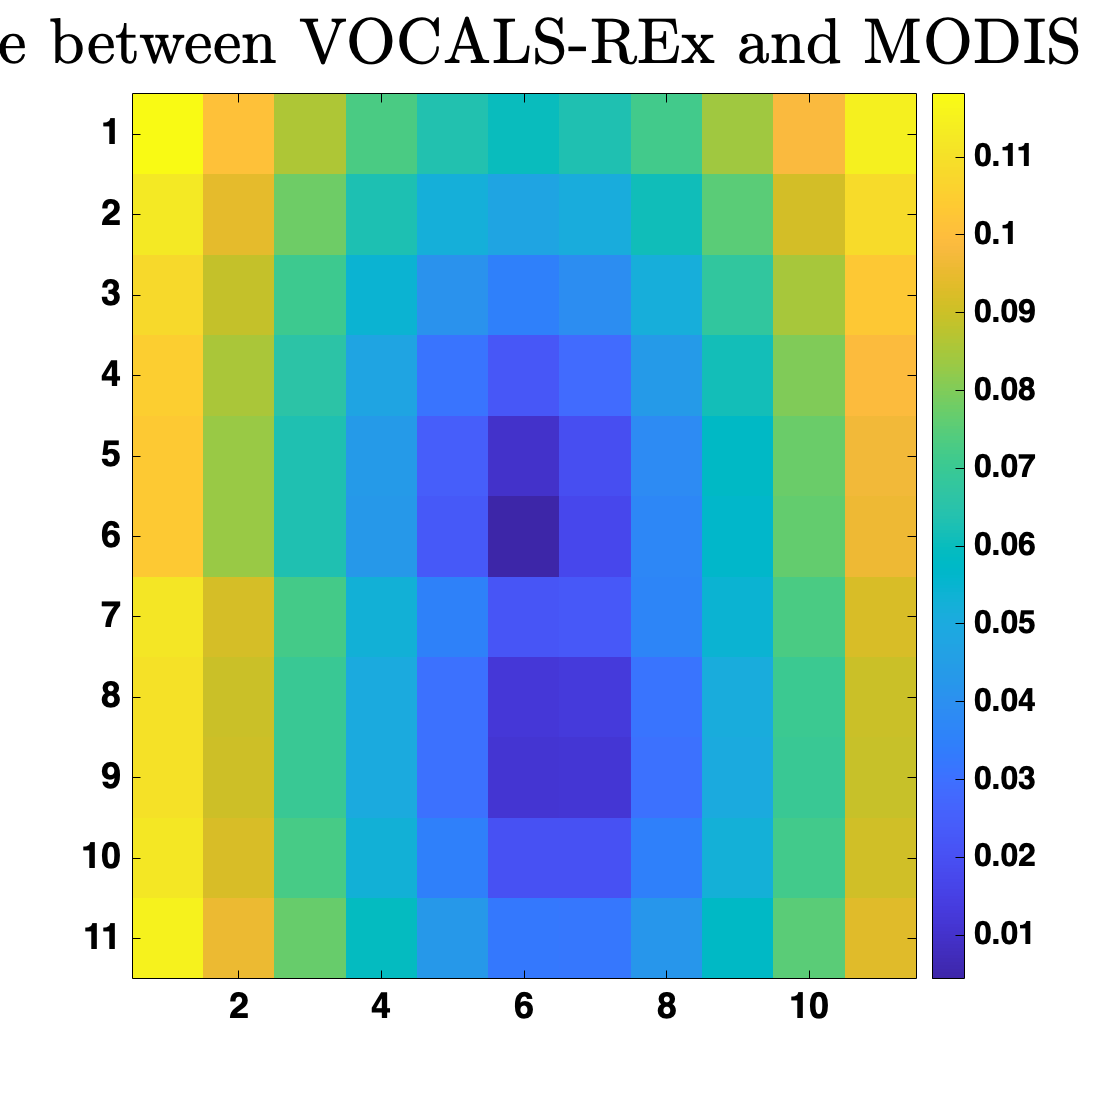

% Find the MODIS pixel closest to the vocalsRex data by using the median of
% the VOCALS-REx latitude and longitude
dist_btwn_VR_median_and_MODIS = sqrt((double(modis.geo.lat) - median(vocalsRex_closest2modis.latitude)).^2 +...
    (double(modis.geo.long) - median(vocalsRex_closest2modis.longitude)).^2); 

% Plot the pixels surounding the pixel with the minimum distance 
[r,c] = ind2sub(size(dist_btwn_VR_median_and_MODIS), vocalsRex_closest2modis.modisIndex_minDist_median);
pixel_window = 5;

figure; 
imagesc(dist_btwn_VR_median_and_MODIS(r-pixel_window:r+pixel_window, c-pixel_window:c+pixel_window))
title('Distance between VOCALS-REx and MODIS pixels', 'Interpreter','latex')
set(gcf, 'Position', [0 0 550 550])
colorbar

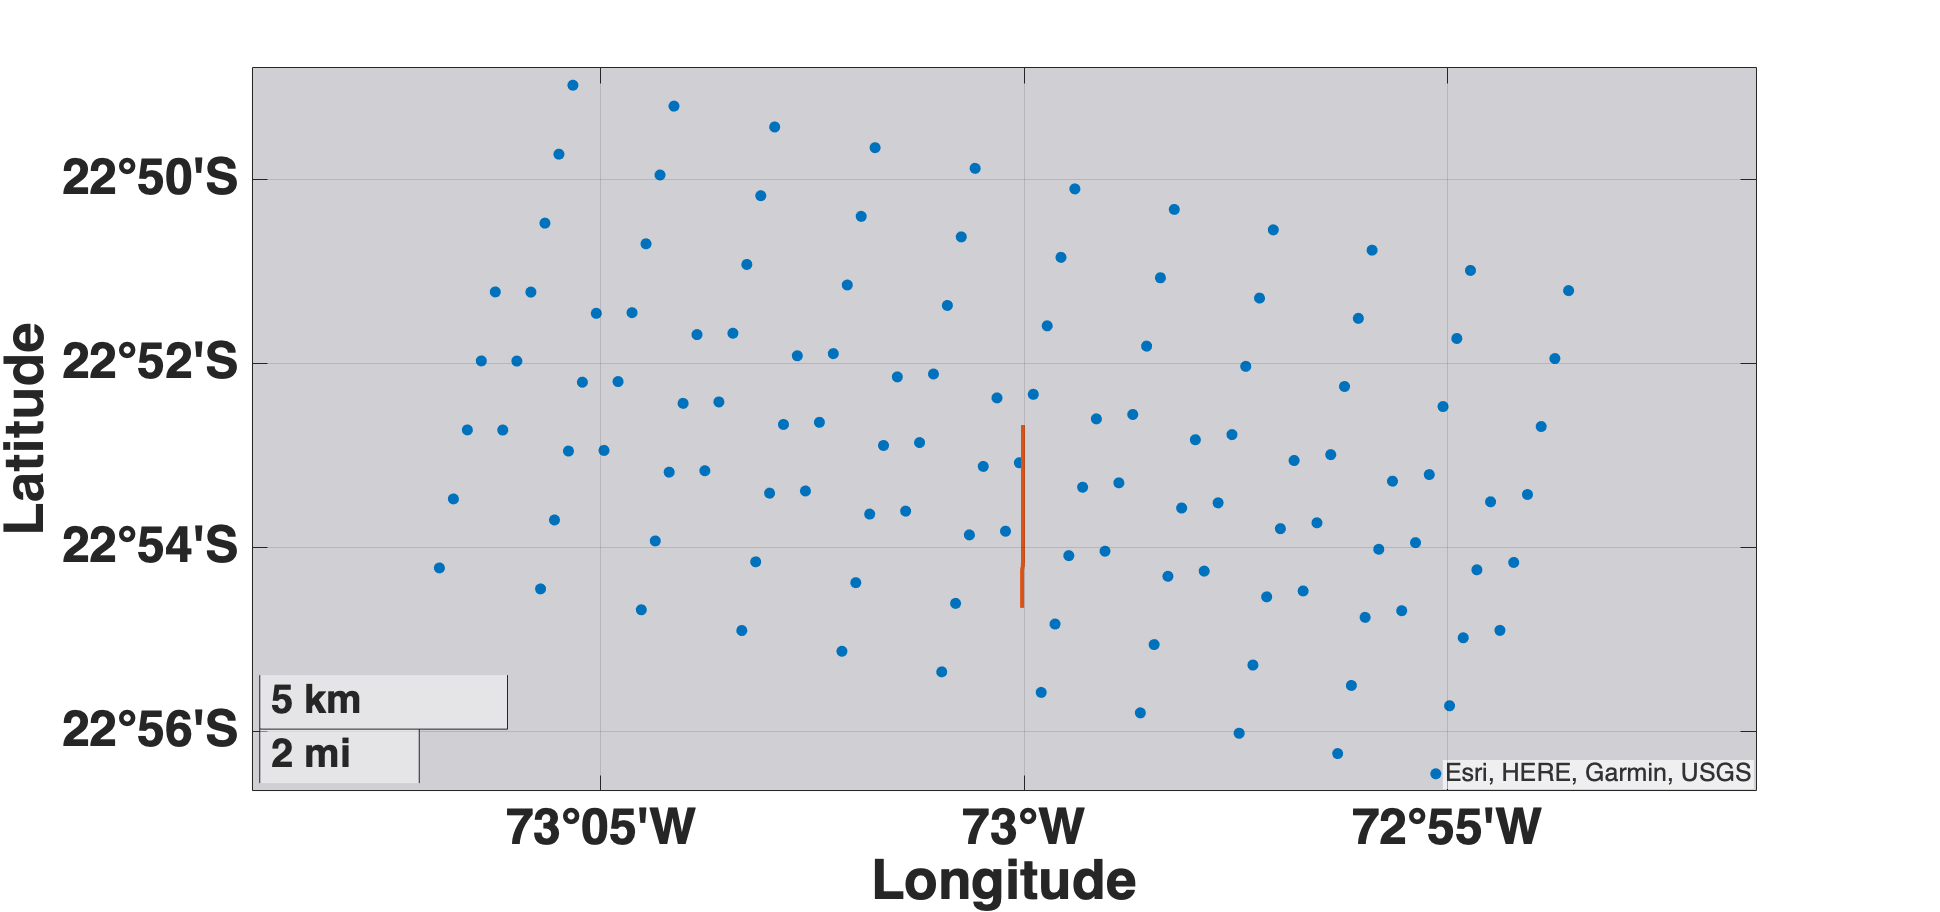

lats2plot = modis.geo.lat(r-pixel_window:r+pixel_window, c-pixel_window:c+pixel_window);
longs2plot = modis.geo.long(r-pixel_window:r+pixel_window, c-pixel_window:c+pixel_window);

figure; geoplot(lats2plot(:), longs2plot(:), '.','MarkerSize', 15)
hold on
geoplot(vocalsRex_closest2modis.latitude, vocalsRex_closest2modis.longitude, '-',...
    'LineWidth', 2)
set(gca, 'FontSize',25)
set(gca, 'FontWeight', 'bold')
set(gcf, 'Position',[0 0 1275, 600])

## Plot all MODIS pixel locations on a scatter plot

% define the pixel window - plotting the entire array results in a
% meaningless figure
pixel_window = 25;
% figure; plot(modis.geo.long(r-pixel_window:r+pixel_window, c-pixel_window:c+pixel_window),...
%     modis.geo.lat(r-pixel_window:r+pixel_window, c-pixel_window:c+pixel_window), '.',...
%     'MarkerSize', 15)
figure; plot(modis.geo.long(:, 1:3),...
    modis.geo.lat(:, 1:3), '.',...
    'MarkerSize', 15)
xlabel('Longitude')
ylabel('Latitude')

## Plot VOCALS-REx cropped data

% Plot VOCALS-REx total number concentration versus altitude and droplet
% size versus altitude

%  Below this, create a subplot with effective radius versus time and
%  altitude versus time


figure; subplot(3,1,1)
semilogy(vocalsRex.time_utc, vocalsRex.Nc); 
grid on; grid minor; 
ylabel('Total $N_c$  $(cm^{3})$','Interpreter','latex')
title('VOCALS-REx flight Data', 'Interpreter','latex')

hold on;
yyaxis right; 
plot(vocalsRex.time_utc, vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% grab current axes
ax1 = gca;


subplot(3,1,2)
plot(vocalsRex.time_utc, vocalsRex.re); 
grid on; grid minor; 
ylabel('$r_e$ $(\mu m)$','Interpreter','latex')

hold on;
yyaxis right; 
plot(vocalsRex.time_utc, vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% grab current axes
ax2 = gca;


subplot(3,1,3)
plot(vocalsRex.time_utc, vocalsRex.lwc); 
grid on; grid minor; 
xlabel('UTC Time','Interpreter','latex')
ylabel('$LWC$ $(g/m^{3})$','Interpreter','latex')

hold on;
yyaxis right; 
plot(vocalsRex.time_utc, vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex')

% grab current axes
ax3 = gca;



linkaxes([ax1 ax2 ax3],'x');


set(gcf, 'Position',[0 0 1275, 700])

## How I've been selecting pixels

## Let's overlay VOCALS-REX flight path with MODIS data

A single MODIS granule takes 5 minutes to record. I'm unsure it the time listed in the MODIS filename is the time when the entire granule is done recording

or the begining or middle of the recording. So let's plot the VOCALS-REx flight track 5 minutes before and after the MODIS data record time

% create an index defined by the time window below
time_window = 2;    % minutes
index_time_log = vocalsRex.time_utc>(modis.time_decimal - time_window/60) & vocalsRex.time_utc<(modis.time_decimal + time_window/60);

% convert the logical array to an indexed array
index_time = find(index_time_log);


% now we need to select the MODIS pixels that overlap with this vocals Rex
% path during the time window above
% Let's find the closest pixel to each location in index_time

min_idx = zeros(1, length(index_time));
min2_idx = zeros(1, length(index_time));

for nn = 1:length(index_time)
    
    % compute the distance between MODIS pixels and VOCALS-Rex
    dist_modis_vocals = sqrt((modis.geo.lat - vocalsRex.latitude(index_time(nn))).^2 + (modis.geo.long - vocalsRex.longitude(index_time(nn))).^2);
    
    % find the minimum value
    [~, min_idx(nn)] = min(dist_modis_vocals,[],'all');

    % Let's also record the second closest pixel
    % set the minimum value to an arbitarily large value
    dist_modis_vocals(min_idx(nn)) = 9999;
    % now find the next smallest value
    [~, min2_idx(nn)] = min(dist_modis_vocals,[],'all');

end

% combine the two minimum indices
min_idx = [min_idx, min2_idx];

% There is bound to many repeats because VOCALS-Rex samples at a high rate
min_idx = unique(min_idx);


% Now let's try plotting the MODIS pixels we found
% Each pixel is a polygon plotted on a geoplot
% pixels are 1km by 1km. To grab the corners, we need to determine how many
% degree the angular change to due 0.5 km

% set a colormarp so that each pixel can be colored according to the MODIS
% effectrive droplet raius
% Lets define the color of each marker to be associated with the droplet
% size
% set the number of colors to be the length of the data to plot
C = colormap(parula(length(min_idx)));

% Longitude circles have a different radius depend on the latitude
% so we have to compute this at every step in the for loop because the
% latitutde is changing
earth_radius = 6371;         % km

pixel_boundaries = zeros(5, 2, length(min_idx));

figure;

for nn = 1:length(min_idx)

    % compute the angular displacement in longitude due to a 0.5km change
    % from the original longitude position
    % it doesn't matter if the latitude angle is positive or negative, so
    % let's take the absolute value
    dLong = km2deg(pixel_size/2, earth_radius * sind(90 - abs(double(modis.geo.lat(min_idx(nn))))));

    pixel_boundaries(:,:,nn) = [double(modis.geo.lat(min_idx(nn)))-dLat, double(modis.geo.long(min_idx(nn)))-dLong;...
                                double(modis.geo.lat(min_idx(nn)))+dLat, double(modis.geo.long(min_idx(nn)))-dLong;...
                                double(modis.geo.lat(min_idx(nn)))+dLat, double(modis.geo.long(min_idx(nn)))+dLong;...
                                double(modis.geo.lat(min_idx(nn)))-dLat, double(modis.geo.long(min_idx(nn)))+dLong;...
                                double(modis.geo.lat(min_idx(nn)))-dLat, double(modis.geo.long(min_idx(nn)))-dLong];

    % create a geopolyshape. This creates a polygon that can be plotted with
    % MATLAB's geoplot functions
    geo_shape = geopolyshape(pixel_boundaries(:,1,nn), pixel_boundaries(:,2,nn));

    geoplot(geo_shape, 'FaceColor',C(nn,:))

    hold on


end

% set the colorbar limits
% set the limits of the colormap to be the min and max value
cb = colorbar;
clim([min(modis.cloud.effRadius17, [],'all'), max(modis.cloud.effRadius17,[], 'all')]);
% set colorbar title
cb.Label.String = '$r_e$ ($\mu m$)';
cb.Label.Interpreter = 'latex';
cb.Label.FontSize = 25;

% ----- PLOT VOCALS REX FLIGHT PATH BEFORE AND AFTER VERTICAL PROFILE -----

% now plot the VOCALS-REx flight path
% Let's color the part of the vocals rex flight path that samples the
% vertical profile in a different color
% index_before_vertical_profile = vocalsRex.time_utc>(modis.time_decimal - time_window/60) & vocalsRex.time_utc<vert_prof.time_utc{2}(1);
% index_after_vertical_profile = vocalsRex.time_utc>vert_prof.time_utc{2}(end) & vocalsRex.time_utc<(modis.time_decimal + time_window/60);
% geoplot(vocalsRex.latitude(index_before_vertical_profile), vocalsRex.longitude(index_before_vertical_profile), '.-', 'Color',...
%     mySavedColors(2, 'fixed'), 'MarkerSize', 4)
% geoplot(vocalsRex.latitude(index_after_vertical_profile), vocalsRex.longitude(index_after_vertical_profile), '.-', 'Color',...
%     mySavedColors(2, 'fixed'), 'MarkerSize', 4)

% ------------------------------------------------------------------------

% ----- PLOT THE VOCALS FLIGHT PATH DURING THE VERTICAL PROFILE -----
% now plot the position of the plane where the vertical profile was sampled
% in a different color
geoplot(vert_prof.latitude{2}, vert_prof.longitude{2}, '.-', 'Color',...
    mySavedColors(5, 'fixed'), 'MarkerSize', 4)
% ------------------------------------------------------------------------

set(gca, 'FontSize',25)
set(gca, 'FontWeight', 'bold')
set(gcf, 'Position', [0 0 800 800])
% set boundaries fow viewing
geolimits([min(vocalsRex.latitude(index_time))-0.1, max(vocalsRex.latitude(index_time))+0.1],[min(vocalsRex.longitude(index_time)), max(vocalsRex.longitude(index_time))])


## Plot all MODIS pixels - how much overlap is there?

% Plot all MODIS pixels
% Each pixel is a polygon plotted on a geoplot
% pixels are 1km by 1km. To grab the corners, we need to determine how many
% degree the angular change to due 0.5 km

% Every latitue circle is the same size (assuming the Earth is a sphere)
% with radius equal to the Earth's
pixel_size = 1;     %km
dLat = km2deg(pixel_size/2, 'Earth');

% Longitude circles have a different radius depend on the latitude
% so we have to compute this at every step in the for loop because the
% latitutde is changing
earth_radius = 6371;         % km

figure;

for rr = 1
    for cc = 1:100


   clear pixel_boundaries

    % compute the angular displacement in longitude due to a 0.5km change
    % from the original longitude position
    % it doesn't matter if the latitude angle is positive or negative, so
    % let's take the absolute value
    dLong = km2deg(pixel_size/2, earth_radius * sind(90 - abs(double(modis.geo.lat(rr,cc)))));

    pixel_boundaries = [double(modis.geo.lat(rr,cc))-dLat, double(modis.geo.long(rr,cc))-dLong;...
                        double(modis.geo.lat(rr,cc))+dLat, double(modis.geo.long(rr,cc))-dLong;...
                        double(modis.geo.lat(rr,cc))+dLat, double(modis.geo.long(rr,cc))+dLong;...
                        double(modis.geo.lat(rr,cc))-dLat, double(modis.geo.long(rr,cc))+dLong;...
                        double(modis.geo.lat(rr,cc))-dLat, double(modis.geo.long(rr,cc))-dLong];

    % create a geopolyshape. This creates a polygon that can be plotted with
    % MATLAB's geoplot functions
    geo_shape = geopolyshape(pixel_boundaries(:,1), pixel_boundaries(:,2));

    geoplot(geo_shape, 'FaceColor',mySavedColors(1, 'fixed'))

    hold on


    end
end

## Compute the km separation between pixels

% Every latitue circle is the same size (assuming the Earth is a sphere)
% with radius equal to the Earth's
pixel_size = 1;     %km


% Longitude circles have a different radius depend on the latitude
% so we have to compute this at every step in the for loop because the
% latitutde is changing
earth_radius = 6371;         % km

num_rows = 1;
num_cols  = size(modis.geo.lat, 2) - 1;

dkm_long = zeros(num_rows, num_cols);
dkm_lat = zeros(num_rows, num_cols);
dkm_pixel = zeros(num_rows, num_cols);

for rr = 1:num_rows
    for cc = 1:num_cols


   clear pixel_boundaries

    % compute the angular displacement in longitude due to a 0.5km change
    % from the original longitude position
    % it doesn't matter if the latitude angle is positive or negative, so
    % let's take the absolute value
    radius_at_lat = earth_radius * sind(90 - abs(double(modis.geo.lat(rr,cc))));
    diff_long = abs(double(modis.geo.long(rr,cc)) - double(modis.geo.long(rr,cc+1)));
    diff_lat = abs(double(modis.geo.lat(rr,cc)) - double(modis.geo.lat(rr,cc+1)));


    dkm_long(rr,cc) = deg2km(diff_long, radius_at_lat);
    dkm_lat(rr,cc) = deg2km(diff_lat, 'Earth');
    dkm_pixel(rr,cc) = sqrt(dkm_long(rr,cc)^2 + dkm_lat(rr,cc)^2);



    end
end


figure; 
plot(modis.sensor.zenith(1,1:end-1), dkm_pixel(:), '.')
ylabel('km between pixels', 'Interpreter','latex')
xlabel('Pixel Zenith Angle (deg)', 'Interpreter','latex')
grid on; grid minor
set(gcf, 'Position', [0 0 800 500])

## Plot the satellite range versus sensor zenith angle

figure; 
plot(modis.sensor.zenith(1,:), modis.sensor.range(1,:)./1e3, '.')
grid on; grid minor
ylabel('Range to satellite (km)', 'Interpreter','latex')
xlabel('Pixel Zenith Angle (deg)', 'Interpreter','latex')
set(gcf, 'Position', [0 0 800 500])

## Let's grab the vertical profiles

% define the minimum liquid water content. This determines the begining and
% end of the vertical profile
LWC_threshold = 0.03;

% Would you like to terminate the vertical profile at the maximum liquid
% water content value?
stop_at_max_LWC = false;

% find all vertical profiles
vert_profs_all = find_verticalProfiles_VOCALS_REx(vocalsRex, LWC_threshold, stop_at_max_LWC);